## Transmitting the bits

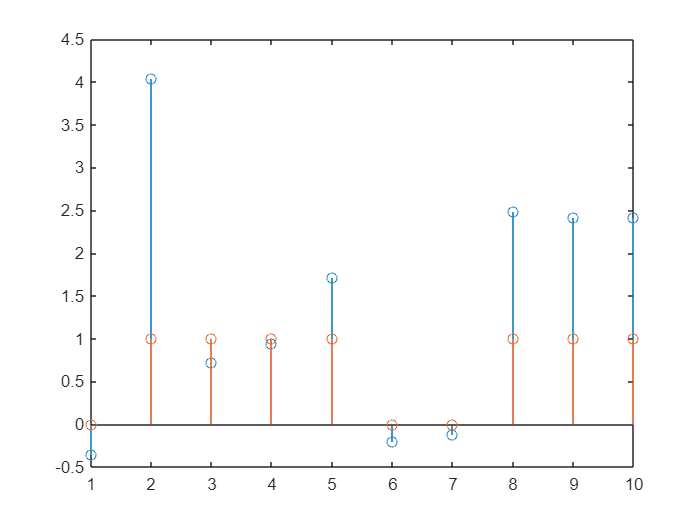

t1 = 1:10;

tx_data10 = randi([0,1], 1, 10);
% disp(tx_data10);

noise10 = randn(1, length(tx_data10));
% disp(noise);

rx_signal10 = tx_data10 + noise10;
% disp(rx_signal);

stem(t1, rx_signal10);
hold on;

output10 = zeros(1,10);

for i = 1:length(rx_signal10)
    if rx_signal10(i) >= 0.5
        output10(i) = 1;
    else
        output10(i) = 0;
    end
end

stem(t1,output10);
hold off;



BER10 = sum(output10 ~= tx_data10)/length(tx_data10);
disp(BER10);

    0.2000



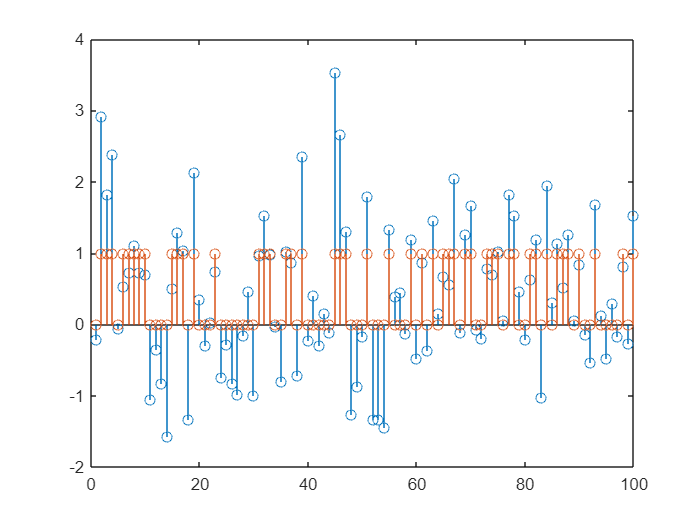

t2 = 1:100;

tx_data100 = randi([0,1], 1, 100);
% disp(tx_data);

noise100 = randn(1, length(tx_data100));
% disp(noise);

rx_signal100 = tx_data100 + noise100;
% disp(rx_signal100);

stem(t2, rx_signal100);
hold on;
output100 = zeros(1,100);

for i = 1:length(rx_signal100)
    if rx_signal100(i) >= 0.5
        output100(i) = 1;
    else
        output100(i) = 0;
    end
end

stem(t2,output100);
hold off;


BER100 = sum(output100 ~= tx_data100)/length(tx_data100);
disp(BER100);

    0.3200



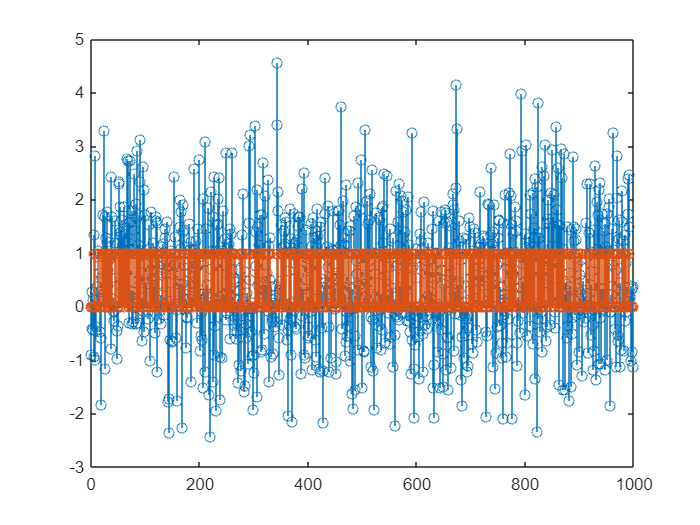

t3 = 1:1000;

tx_data1000 = randi([0,1], 1, 1000);
% disp(tx_data);

noise1000 = randn(1, length(tx_data1000));
% disp(noise1000);

rx_signal1000 = tx_data1000 + noise1000;
% disp(rx_signal1000);

stem(t3, rx_signal1000);
hold on;
output1000 = zeros(1,1000);

for i = 1:length(rx_signal1000)
    if rx_signal1000(i) >= 0.5
        output1000(i) = 1;
    else
        output1000(i) = 0;
    end
end

stem(t3,output1000);
hold off;


BER1000 = sum(output1000 ~= tx_data1000)/length(tx_data1000);
disp(BER1000);

    0.2760



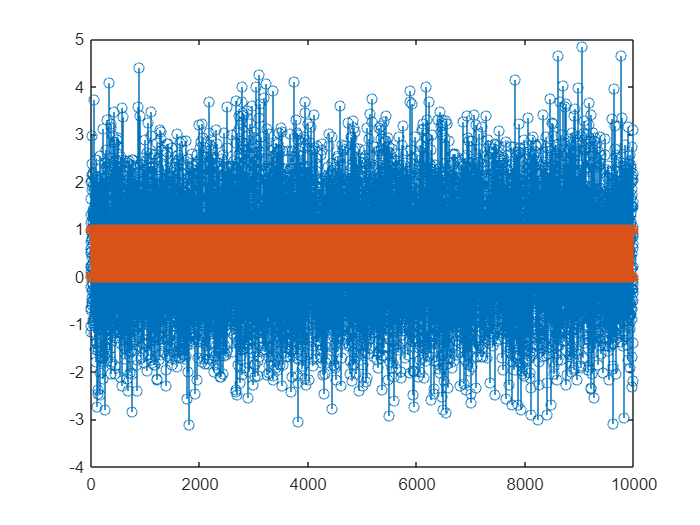

t4 = 1:10000;

tx_data10000 = randi([0,1], 1, 10000);
% disp(tx_data);

noise10000 = randn(1, length(tx_data10000));
% disp(noise);

rx_signal10000 = tx_data10000 + noise10000;
% disp(rx_signal10000);

stem(t4, rx_signal10000);
hold on;
output10000 = zeros(1,10000);

for i = 1:length(rx_signal10000)
    if rx_signal10000(i) >= 0.5
        output10000(i) = 1;
    else
        output10000(i) = 0;
    end
end

stem(t4,output10000);
hold off;


BER10000 = sum(output10000 ~= tx_data10000)/length(tx_data10000);
disp(BER10000);

    0.3016



## Transmitting the bits with the power of 5

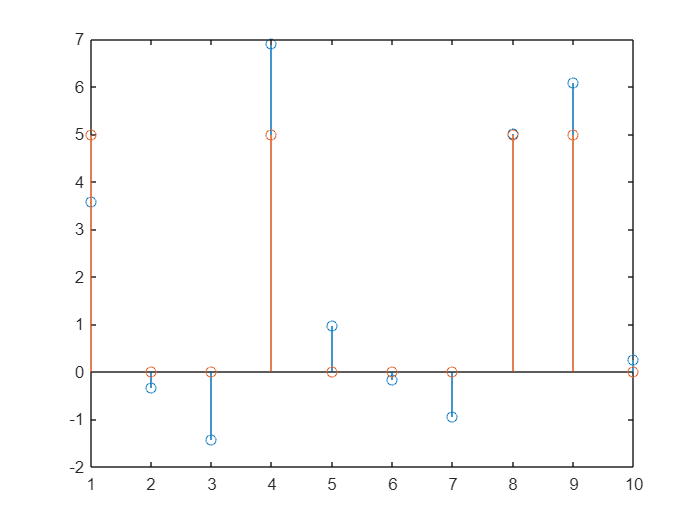


t5 = 1:10;

tx_data10_with_power = 5 * randi([0,1], 1, 10);
% disp(tx_data10_with_power);

wnoise10 = randn(1, length(tx_data10_with_power));
% disp(wnoise10);

rx_signal_with_power = tx_data10_with_power + wnoise10;
% disp(rx_signal_with_power);

stem(t5, rx_signal_with_power);
hold on;

output10_with_power = zeros(1,10);

for i = 1:length(rx_signal_with_power)
    if rx_signal_with_power(i) >= 2.5
        output10_with_power(i) = 5;
    else
        output10_with_power(i) = 0;
    end
end

stem(t5,output10_with_power);
hold off;



BER10_with_power = sum(output10_with_power ~= tx_data10_with_power)/ length(tx_data10_with_power);
disp(BER10_with_power);

     0



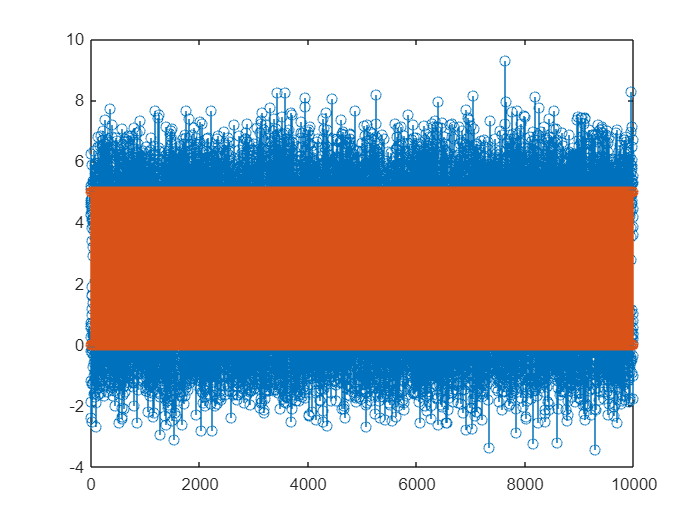

t6 = 1:10000;

tx_data10000_with_power = 5 * randi([0,1], 1, 10000);
% disp(tx_data10000);

wnoise10000 = randn(1, length(tx_data10000_with_power));
% disp(wnoise10000);

rx_signal10000_with_power = tx_data10000_with_power + wnoise10000;
% disp(rx_signal10000_with_power);

stem(t6, rx_signal10000_with_power);
hold on;
output10000_with_power = zeros(1,10000);

for i = 1:length(rx_signal10000_with_power)
    if rx_signal10000_with_power(i) >= 2.5
        output10000_with_power(i) = 5;
    else
        output10000_with_power(i) = 0;
    end
end

stem(t6,output10000_with_power);
hold off;


BER10000_with_power = sum(output10000_with_power ~= tx_data10000_with_power)/length(tx_data10000_with_power);
disp(BER10000_with_power);

    0.0061



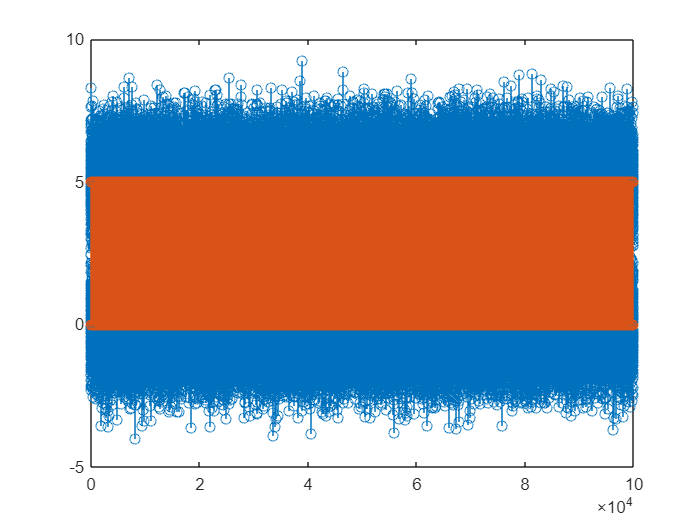

t7 = 1:100000;

% Transmit: 0 and 5 (not just binary 0/1)
tx_data100000_with_power = 5 * randi([0,1], 1, 100000);

wnoise100000 = randn(1, length(tx_data100000_with_power));

rx_signal100000_with_power = tx_data100000_with_power + wnoise100000;

stem(t7, rx_signal100000_with_power);
hold on;

output100000_with_power = zeros(1,100000);

for i = 1:length(rx_signal100000_with_power)
    if rx_signal100000_with_power(i) >= 2.5
        output100000_with_power(i) = 5;
    else
        output100000_with_power(i) = 0;
    end
end

stem(t7, output100000_with_power);
hold off;


% Correct BER
BER100000_with_power = sum(output100000_with_power ~= tx_data100000_with_power) / length(tx_data100000_with_power);
disp(BER100000_with_power);

    0.0060



## Transmitting the bits with the weaker noise

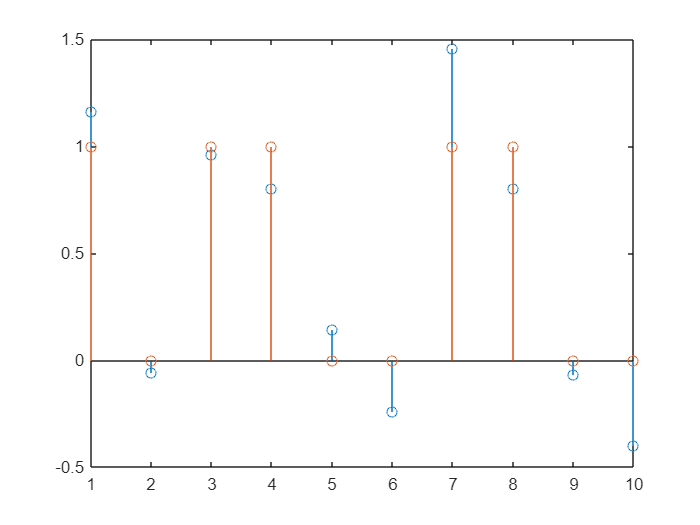

t8 = 1:10;

tx_data10_weaker_noise = randi([0,1], 1, 10);
% disp(tx_data10);

noise10_weaker = 1/5 * randn(1, length(tx_data10_weaker_noise));
% disp(noise);

rx_signal10_weaker = tx_data10_weaker_noise + noise10_weaker;
% disp(rx_signal);

stem(t8, rx_signal10_weaker);
hold on;

output10_weaker = zeros(1,10);

for i = 1:length(rx_signal10_weaker)
    if rx_signal10_weaker(i) >= 0.5
        output10_weaker(i) = 1;
    else
        output10_weaker(i) = 0;
    end
end

stem(t8,output10_weaker);
hold off;



BER10_weaker = sum(output10_weaker ~= tx_data10_weaker_noise)/length(tx_data10_weaker_noise);
disp(BER10_weaker);

     0



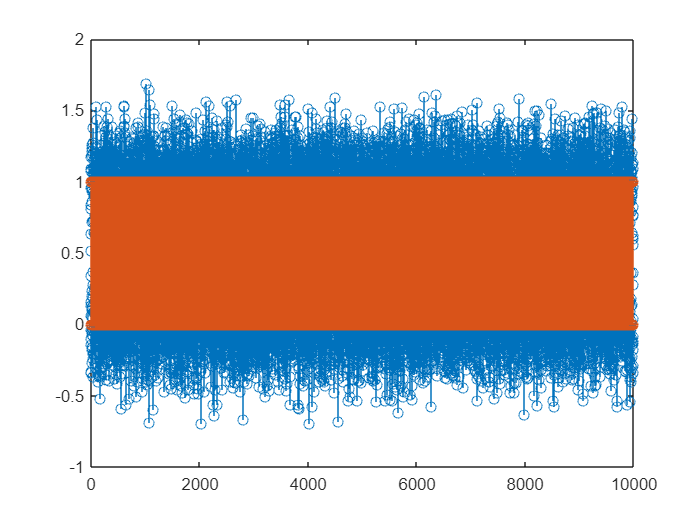

t9 = 1:10000;

tx_data10000_weaker_noise = randi([0,1], 1, 10000);
% disp(tx_data10);

noise10000_weaker = 1/5 * randn(1, length(tx_data10000_weaker_noise));
% disp(noise);

rx_signal10000_weaker = tx_data10000_weaker_noise + noise10000_weaker;
% disp(rx_signal);

stem(t9, rx_signal10000_weaker);
hold on;

output10000_weaker = zeros(1,10000);

for i = 1:length(rx_signal10000_weaker)
    if rx_signal10000_weaker(i) >= 0.5
        output10000_weaker(i) = 1;
    else
        output10000_weaker(i) = 0;
    end
end

stem(t9,output10000_weaker);
hold off;



BER10000_weaker = sum(output10000_weaker ~= tx_data10000_weaker_noise)/length(tx_data10000_weaker_noise);
disp(BER10000_weaker);

    0.0062



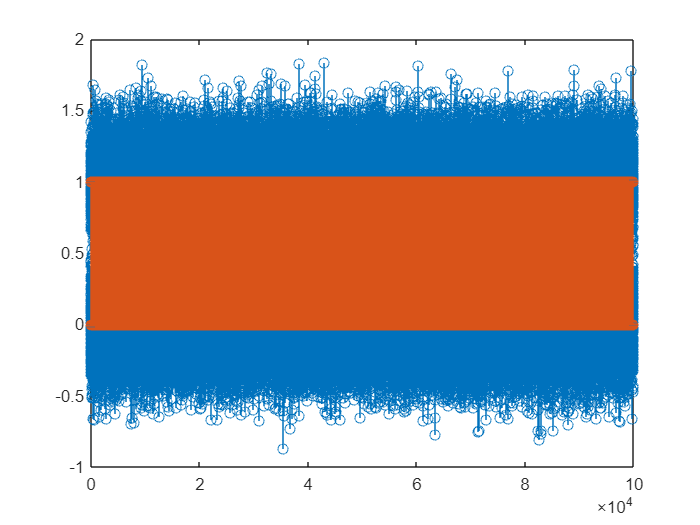

t10 = 1:100000;

tx_data100000_weaker_noise = randi([0,1], 1, 100000);
% disp(tx_data10);

noise100000_weaker = 1/5 * randn(1, length(tx_data100000_weaker_noise));
% disp(noise);

rx_signal100000_weaker = tx_data100000_weaker_noise + noise100000_weaker;
% disp(rx_signal);

stem(t10, rx_signal100000_weaker);
hold on;

output100000_weaker = zeros(1,100000);

for i = 1:length(rx_signal100000_weaker)
    if rx_signal100000_weaker(i) >= 0.5
        output100000_weaker(i) = 1;
    else
        output100000_weaker(i) = 0;
    end
end

stem(t10,output100000_weaker);
hold off;



BER100000_weaker = sum(output100000_weaker ~= tx_data100000_weaker_noise) / length(tx_data100000_weaker_noise);
disp(BER100000_weaker);

    0.0063



## SNR value

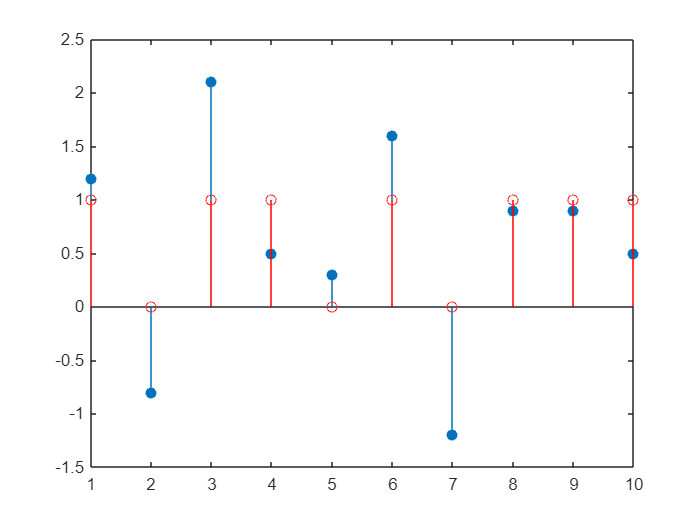

% SNR by hand values------------------------------paper :)

% SNR by Matlab values----------------------------
% Time axis
t_sn = 1:10;

% Transmitted signal & % Additive white Gaussian noise
tx_sn = [1 0 1 1 0 1 0 0 1 0];
noise_sn = [0.2 -0.8 1.1 -0.5 0.3 0.6 -1.2 0.9 -0.1 0.5];


% Received signal
rx_sn = tx_sn + noise_sn;

% Plot received signal
stem(t_sn, rx_sn, 'filled');
hold on;

% Initialize decoded output
output_sn = zeros(1,10);

% Decision rule: threshold at 0.5
for i = 1:length(rx_sn)
    if rx_sn(i) >= 0.5
        output_sn(i) = 1;
    else
        output_sn(i) = 0;
    end
end

% Plot decoded output
stem(t_sn, output_sn, 'r');
hold off;


% ====== SNR Calculation ======
P_signal_sn = mean(abs(tx_sn).^2);      % Signal power
P_noise_sn = mean(abs(noise_sn).^2);    % Noise power

SNR_linear_sn = P_signal_sn / P_noise_sn;
SNR_dB_sn = 10 * log10(SNR_linear_sn);

% ====== Display Results ======
disp(['Signal Power = ', num2str(P_signal_sn)]);

Signal Power = 0.5


disp(['Noise Power = ', num2str(P_noise_sn)]);

Noise Power = 0.51


disp(['SNR (linear) = ', num2str(SNR_linear_sn)]);

SNR (linear) = 0.98039


disp(['SNR (dB) = ', num2str(SNR_dB_sn)]);

SNR (dB) = -0.086002


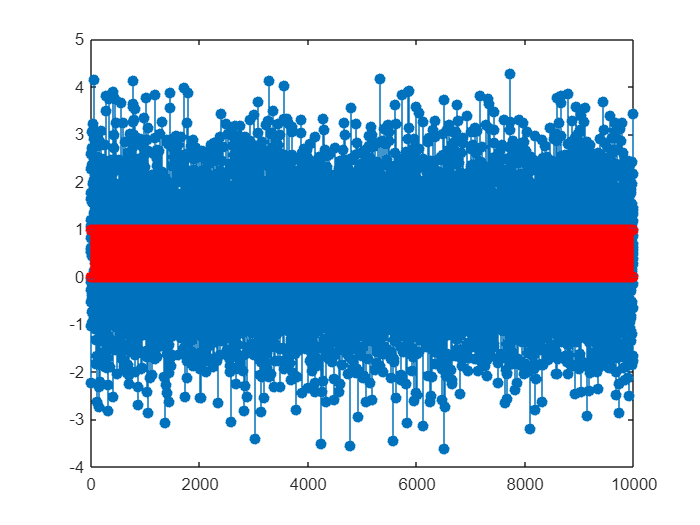

% SNR by Matlab values----------------------------10000
% Time axis
t_sn10000 = 1:10000;


% Transmitted signal & % Additive white Gaussian noise
tx_sn10000 = randi([0,1], 1, 10000);
noise_sn10000 = randn(1, length(tx_sn10000));


% Received signal
rx_sn10000 = tx_sn10000 + noise_sn10000;

% Plot received signal
stem(t_sn10000, rx_sn10000, 'filled');
hold on;

% Initialize decoded output
output_sn10000 = zeros(1,10000);


% Decision rule: threshold at 0.5
for i = 1:length(rx_sn10000)
    if rx_sn10000(i) >= 0.5
        output_sn10000(i) = 1;
    else
        output_sn10000(i) = 0;
    end
end

% Plot decoded output
stem(t_sn10000, output_sn10000, 'r');
hold off;


% ====== SNR Calculation ======
P_signal_sn10000 = mean(abs(tx_sn10000).^2);      % Signal power
P_noise_sn10000 = mean(abs(noise_sn10000).^2);    % Noise power

SNR_linear_sn10000 = P_signal_sn / P_noise_sn;
SNR_dB_sn10000 = 10 * log10(SNR_linear_sn);

% ====== Display Results ======
disp(['Signal Power = ', num2str(P_signal_sn10000)]);

Signal Power = 0.4992


disp(['Noise Power = ', num2str(P_noise_sn10000)]);

Noise Power = 0.9911


disp(['SNR (linear) = ', num2str(SNR_linear_sn10000)]);

SNR (linear) = 0.98039


disp(['SNR (dB) = ', num2str(SNR_dB_sn10000)]);

SNR (dB) = -0.086002


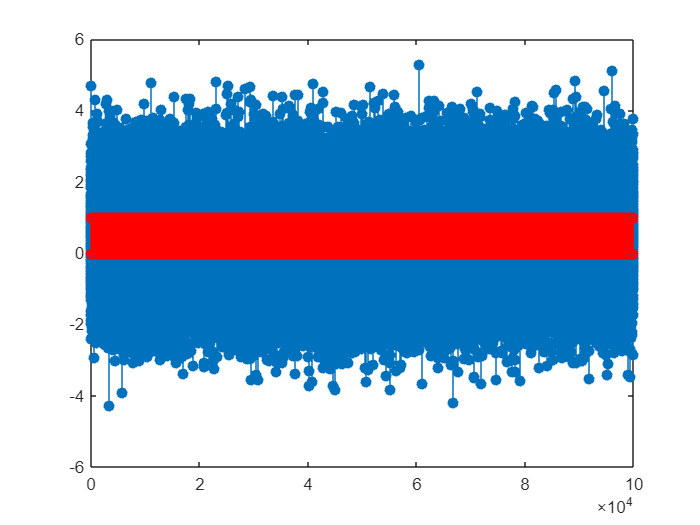

% SNR by Matlab values----------------------------100000
% Time axis
t_sn100000 = 1:100000;


% Transmitted signal & % Additive white Gaussian noise
tx_sn100000 = randi([0,1], 1, 100000);
noise_sn100000 = randn(1, length(tx_sn100000));


% Received signal
rx_sn100000 = tx_sn100000 + noise_sn100000;

% Plot received signal
stem(t_sn100000, rx_sn100000, 'filled');
hold on;

% Initialize decoded output
output_sn100000 = zeros(1,100000);


% Decision rule: threshold at 0.5
for i = 1:length(rx_sn100000)
    if rx_sn100000(i) >= 0.5
        output_sn100000(i) = 1;
    else
        output_sn100000(i) = 0;
    end
end

% Plot decoded output
stem(t_sn100000, output_sn100000, 'r');
hold off;


% ====== SNR Calculation ======
P_signal_sn100000 = mean(abs(tx_sn100000).^2);      % Signal power
P_noise_sn100000 = mean(abs(noise_sn100000).^2);    % Noise power

SNR_linear_sn100000 = P_signal_sn / P_noise_sn;
SNR_dB_sn100000 = 10 * log10(SNR_linear_sn);

% ====== Display Results ======
disp(['Signal Power = ', num2str(P_signal_sn100000)]);

Signal Power = 0.50192


disp(['Noise Power = ', num2str(P_noise_sn100000)]);

Noise Power = 0.99985


disp(['SNR (linear) = ', num2str(SNR_linear_sn100000)]);

SNR (linear) = 0.98039


disp(['SNR (dB) = ', num2str(SNR_dB_sn100000)]);

SNR (dB) = -0.086002


## SNR TARGET = 10dB

% Generate signal
tx_manual = randi([0,1], 1, 100000);
P_signal_manual = mean(abs(tx_manual).^2);   % ~0.5 for binary signals

% Try different noise scaling factors
scales = [1.0, 0.8, 0.6, 0.4, 0.35, 0.3, 0.25, 0.2];

for s = scales
    % Generate noise with manual scale
    noise_manual = s * randn(1, length(tx_manual));
    rx_manual = tx_manual + noise_manual;

    % Calculate actual noise power and SNR
    P_noise_manual = mean(abs(noise_manual).^2);
    SNR_dB_manual = 10 * log10(P_signal_manual / P_noise_manual);

    % Decode
    decoded_manual = zeros(1, length(rx_manual));
    for i = 1:length(rx_manual)
        if rx_manual(i) >= 0.5
            decoded_manual(i) = 1;
        else
            decoded_manual(i) = 0;
        end
    end

    % Calculate BER
    BER_manual = sum(decoded_manual ~= tx_manual) / length(tx_manual);

    % Show result for this scale
    fprintf('Scale = %.2f | SNR = %.2f dB | BER = %.5f\n', s, SNR_dB_manual, BER_manual);
end

Scale = 1.00 | SNR = -3.03 dB | BER = 0.30938
Scale = 0.80 | SNR = -1.05 dB | BER = 0.26779
Scale = 0.60 | SNR = 1.41 dB | BER = 0.20415
Scale = 0.40 | SNR = 4.94 dB | BER = 0.10606
Scale = 0.35 | SNR = 6.08 dB | BER = 0.07735
Scale = 0.30 | SNR = 7.43 dB | BER = 0.04846
Scale = 0.25 | SNR = 9.05 dB | BER = 0.02275
Scale = 0.20 | SNR = 10.98 dB | BER = 0.00579


% SNR values (in dB)
snr_vals_db = [4, 6, 8, 10, 12, 14];
ber_vals = zeros(1, length(snr_vals_db));

% Generate binary signal
tx_bits = randi([0,1], 1, 100000);
signal_power = mean(abs(tx_bits).^2);  % Should be ~0.5

for k = 1:length(snr_vals_db)
    current_snr_db = snr_vals_db(k);
    current_snr_linear = 10^(current_snr_db / 10);
    
    % Calculate required noise power
    required_noise_power = signal_power / current_snr_linear;

    % Generate and scale noise
    raw_noise = randn(1, length(tx_bits));
    scale = sqrt(required_noise_power / mean(abs(raw_noise).^2));
    scaled_noise = raw_noise * scale;

    % Transmit over noisy channel
    received_signal = tx_bits + scaled_noise;

    % Decode using threshold
    decoded_bits = zeros(1, length(received_signal));
    for i = 1:length(received_signal)
        if received_signal(i) >= 0.5
            decoded_bits(i) = 1;
        else
            decoded_bits(i) = 0;
        end
    end

    % Compute BER
    ber_vals(k) = sum(decoded_bits ~= tx_bits) / length(tx_bits);
end

% Display the table of SNR and BER
fprintf('\n%-10s | %-15s\n', 'SNR (dB)', 'BER');

SNR (dB)   | BER            


fprintf('-----------------------------\n');

-----------------------------


for k = 1:length(snr_vals_db)
    fprintf('%-10d | %-15.5f\n', snr_vals_db(k), ber_vals(k));
end

4          | 0.13206        
6          | 0.07924        
8          | 0.03760        
10         | 0.01276        
12         | 0.00255        
14         | 0.00027        


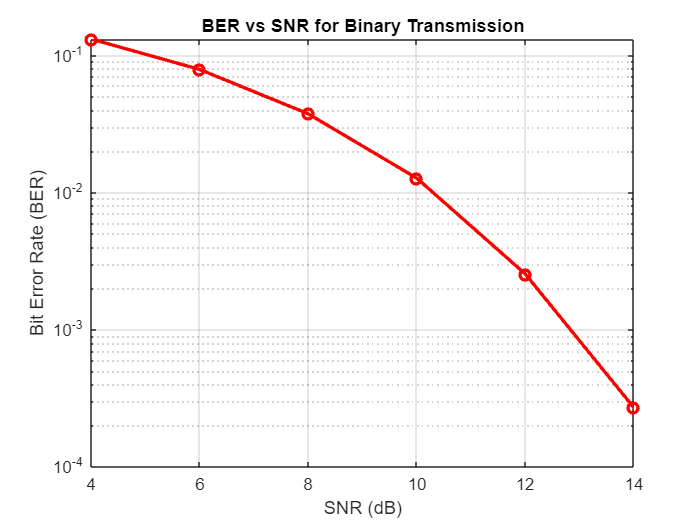



% Plot BER vs SNR
figure;
semilogy(snr_vals_db, ber_vals, '-or', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER vs SNR for Binary Transmission');